# Laboratorium 3 - Powierzchnie drugiego stopnia  

#### Zadanie 1

Narysuj wykres sfery zadanej równaniem $x^2 +y^2 +z^2 =1$ z wykorzystaniem współrzędnych cylindrycznych.

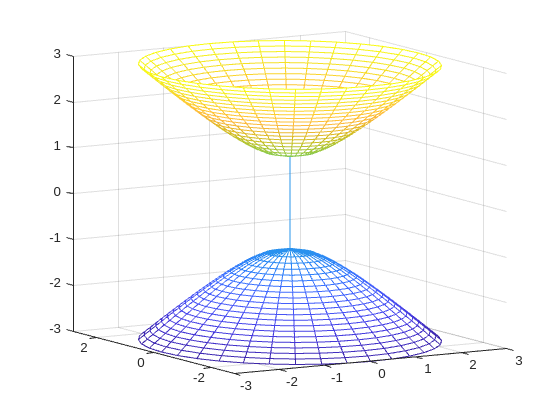

z = [-3:0.1:-1, 1:0.1:3];
theta = 0:pi/18:2*pi;
[Z, THETA] = meshgrid(z, theta);
R = sqrt(Z.^2 - 1);
X = R.*cos(THETA);
Y = R.*sin(THETA);
mesh(X, Y, Z)

#### Zadanie 2

Napisz funkcję o parametrach $a,b,c$ sporządzającą wykres elipsoidy zadanej równaniem $\frac{x^2 }{a^2 }+\frac{y^2 }{b^2 }+\frac{z^2 }{c^2 }=1$ z wykorzystaniem współrzędnych cylindrycznych.

Sporządź wykresy następujących elipsoid: 

-  
$$x^2 +y^2 +z^2 =1$$


- 
$$0\ldotp 25\;x^2 +y^2 +z^2 =1$$


- 
$$x^2 +y^2 +0\ldotp 1\;z^2 =1$$


- 
$$x^2 +0\ldotp 25\;y^2 +0\ldotp 1\;z^2 =1$$


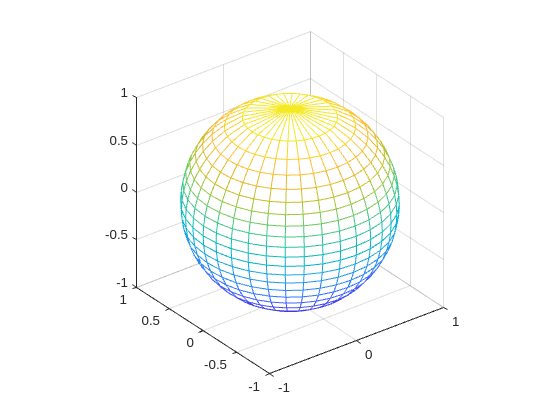

plotEllipsoid(1, 1, 1);

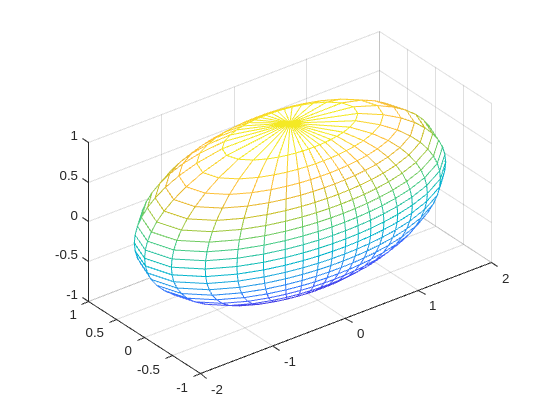

plotEllipsoid(sqrt(4), 1, 1);

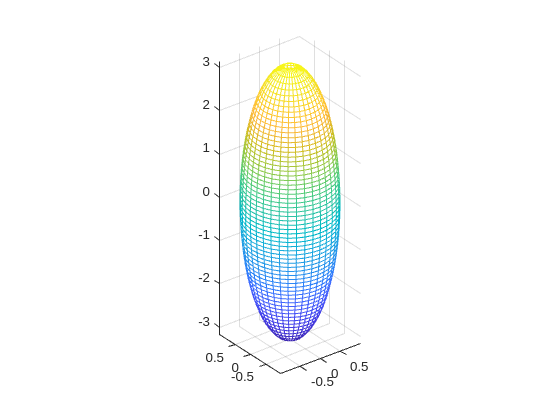

plotEllipsoid(1, 1, sqrt(10));

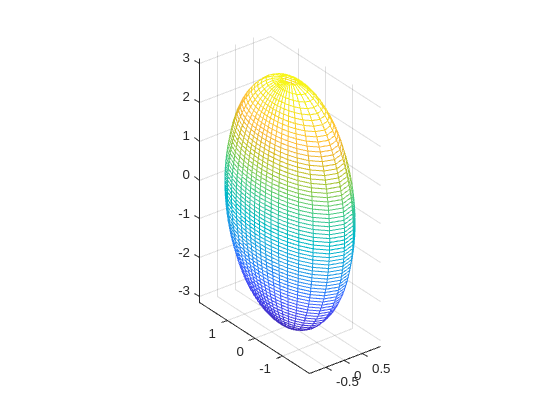

plotEllipsoid(1, sqrt(4), sqrt(10));

#### Zadanie 3

Narysuj wykres hiperboloidy 2-powłokowej eliptycznej zadanej równaniem $-0\ldotp 1\;x^2 -y^2 +z^2 =1$ z wykorzystaniem współrzędnych cylindrycznych.

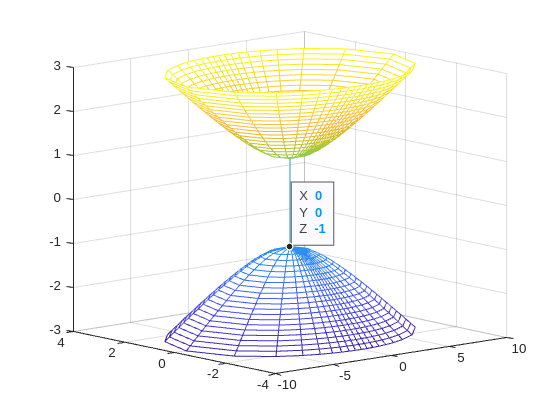

z = [-3:0.1:-1, 1:0.1:3];
theta = 0:pi/18:2*pi;
[Z, THETA] = meshgrid(z, theta);
R = 2*sqrt(5)*sqrt(Z.^2 - 1) ./ sqrt(11 - 9 .* cos(2.*THETA));
X = R.*cos(THETA);
Y = R.*sin(THETA);
mesh(X, Y, Z);

#### Zadanie 4

Narysuj wykres siodła zadanego równaniem $x^2 -0\ldotp 25\;y^2 +z=1$ z wykorzystaniem współrzędnych kartezjańskich.

#### Zadanie 5

Narysuj wykres walca eliptycznego zadanego równaniem $x^2 +0\ldotp 25\;y^2 =1$ 

x = r * cos alpha

y = r * sin alpha

z = z

z^2 - x^2 - y^2 = 1

z^2 - r^2 = 1

r = sqrt(z^2 - 1)

(z^2 - 1) >= 0

z >= 1 && z <= -1

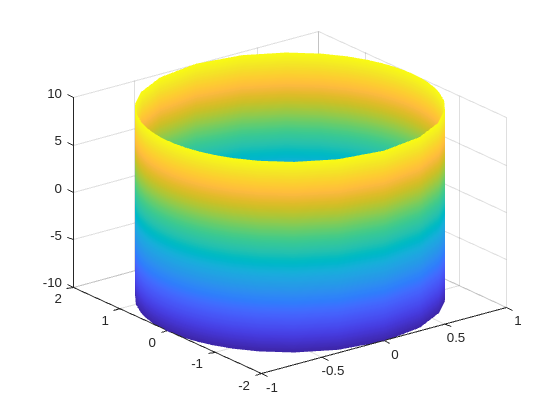

z = -10:0.1:10;
theta = 0:pi/18:2*pi;
[Z, THETA] = meshgrid(z, theta);
R = 2*sqrt(2) ./ sqrt(3 .* cos (2*THETA) + 5);
X = R.*cos(THETA);
Y = R.*sin(THETA);
mesh(X, Y, Z);

function plotEllipsoid(a, b, c)
    z = -c:0.1:c;
    theta = 0:pi/18:2*pi;
    [Z, THETA] = meshgrid(z, theta);
    R = (a * b * sqrt(c^2 - Z.^2)) ./ (sqrt(c^2*(a^2*sin(THETA).^2 + b^2*cos(THETA).^2)));
    cos(THETA);
    X = R.*cos(THETA);
    Y = R.*sin(THETA);
    mesh(X, Y, Z);
    axis equal;
end